# noise

clear;
Fs = 44100;
T = 1 / Fs;
L = Fs * 1;
% X = zeros(L, 1);
t = (0:L-1)*T;
% size(X)
% mags = zeros(1, L/2+1) + 1;
% mags = randn(1, L/2+1);
mags = linspace(0, 1, L/2 + 1);
mags = mags - 0.025

mags =    -0.0250   -0.0250   -0.0249   -0.0249   -0.0248   -0.0248   -0.0247   -0.0247   -0.0246   -0.0246   -0.0245   -0.0245   -0.0245   -0.0244   -0.0244   -0.0243   -0.0243   -0.0242   -0.0242   -0.0241   -0.0241   -0.0240   -0.0240   -0.0240   -0.0239   -0.0239   -0.0238   -0.0238   -0.0237   -0.0237   -0.0236   -0.0236   -0.0235   -0.0235   -0.0235   -0.0234   -0.0234   -0.0233   -0.0233   -0.0232   -0.0232   -0.0231   -0.0231   -0.0230   -0.0230   -0.0230   -0.0229   -0.0229   -0.0228   -0.0228


mags = exp(-200000*mags.*mags);
mags = mags - min(mags)

mags =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


% phases = zeros(1, L/2+1);
% phases = randn(1, L/2+1);
phases = rand(1, L/2+1);
% phases = mod(randn(1, L/2+1), 1);
% phases = linspace(pi, -pi, L/2 + 1);
% phases = tan(phases*20200);
phases = phases - min(phases);
phases = phases / max(phases);
phases = (phases - 0.5) * 2;
phases = phases * pi;

f = Fs/L*(0:(L/2));
plot(f(1:end/10),mags(1:end/10)) 

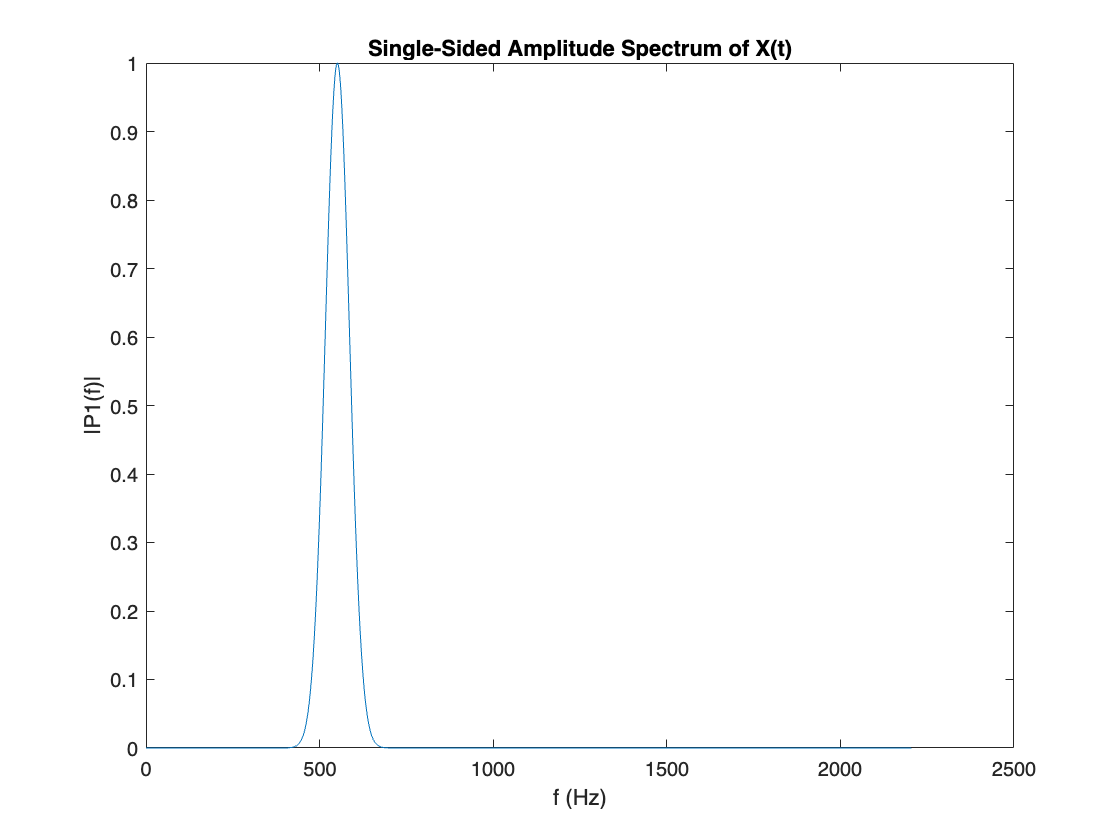

title("Single-Sided Amplitude Spectrum of X(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

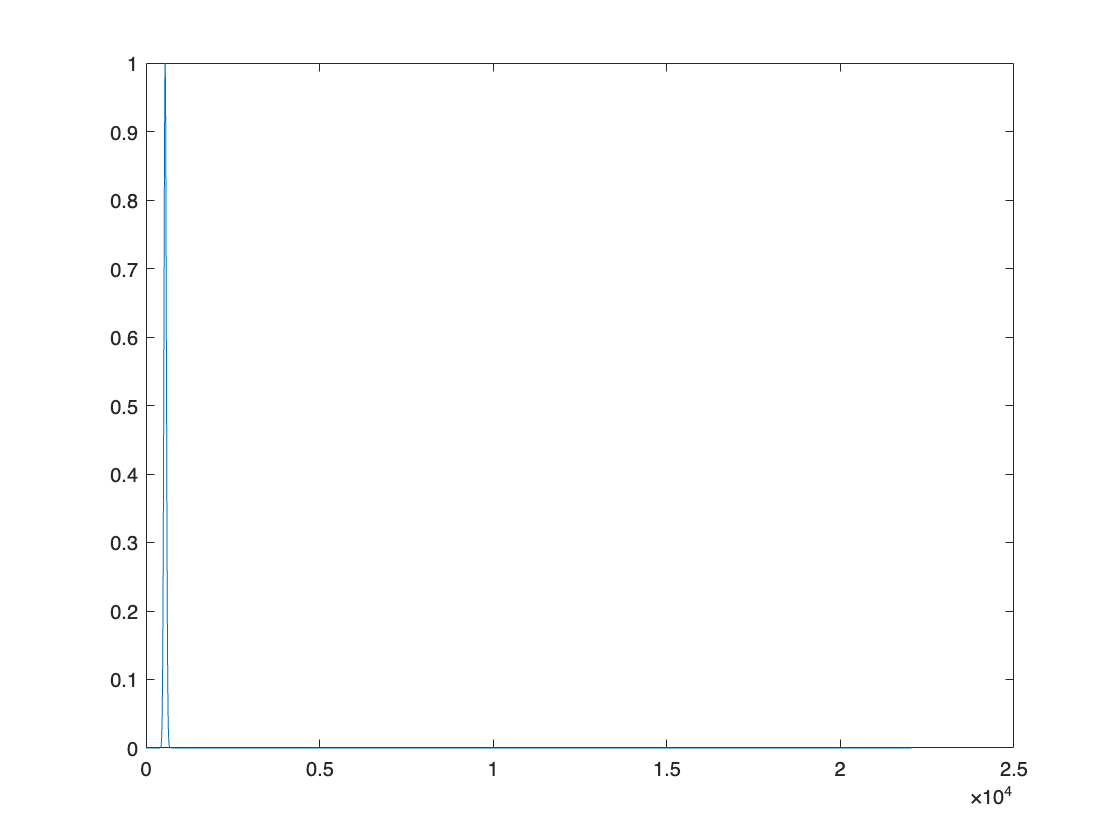

plot(f,mags)

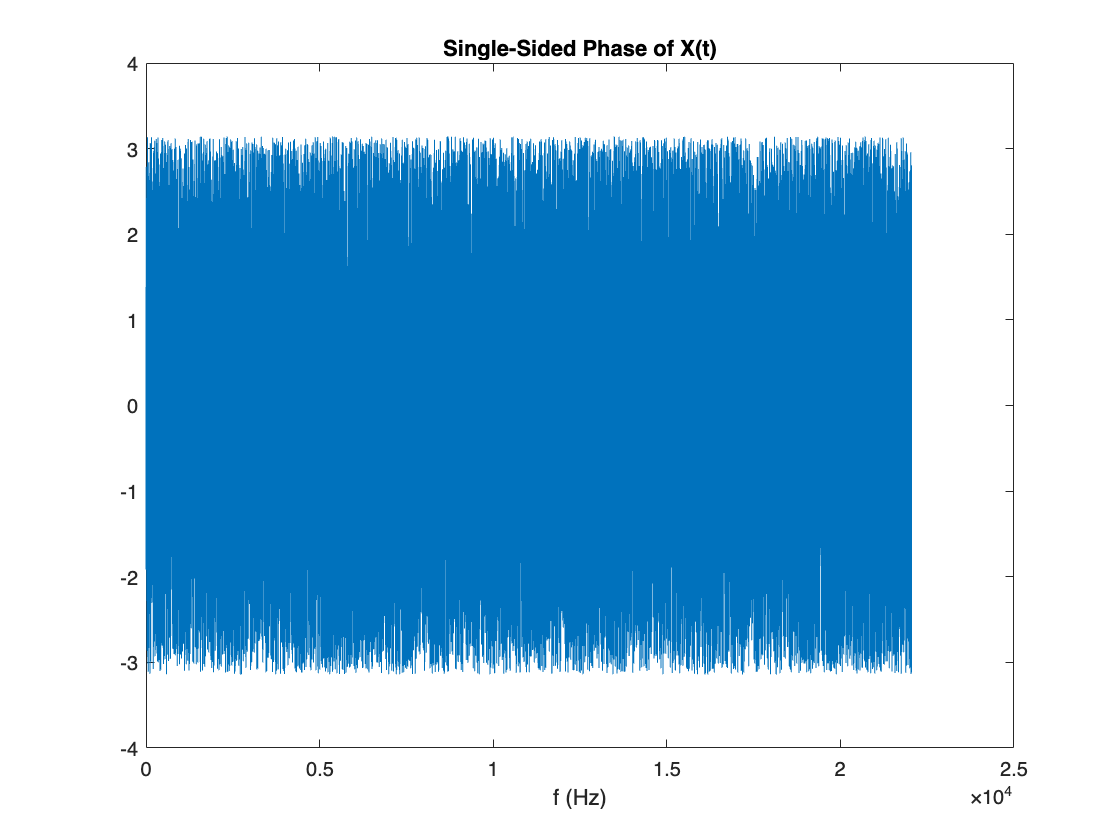


f = Fs/L*(0:(L/2));
plot(f,phases) 
title("Single-Sided Phase of X(t)")
xlabel("f (Hz)")

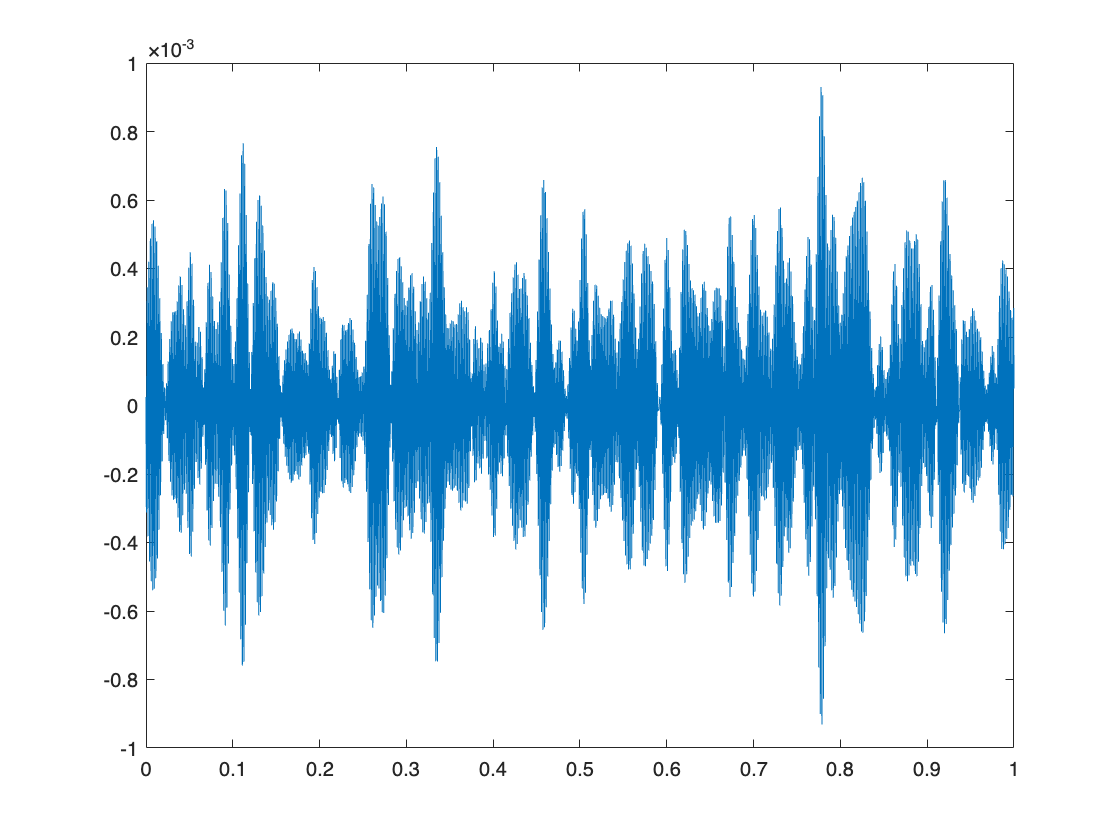


recs = zeros(1, L);
for i = 0:(L/2)
    mag = mags(i+1);
    phase = phases(i+1);
    add = 2*mag/L * cos(2*pi*t*Fs/L*i + 1*phase);
    if i == 0 || i == L/2
        add = add / 2;
    end
    recs = recs + add;
end
plot(t,recs);

recs(1)

ans = 2.5578e-05

recs(end)

ans = 4.8914e-05

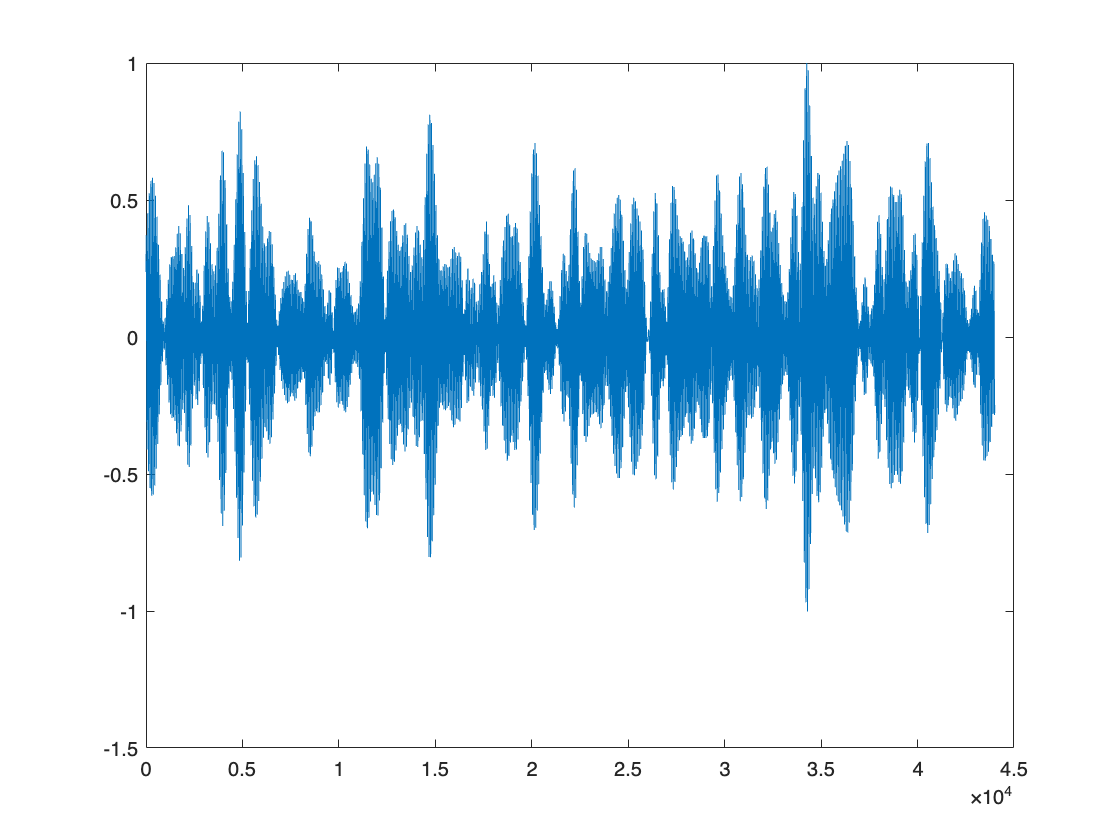

smoothening = 50;

recs = recs(1+smoothening:end-smoothening);
recs = recs / max(recs);
plot((1:L - 2*smoothening),recs);


prepend = linspace(0, recs(1), smoothening)

prepend =          0    0.0049    0.0097    0.0146    0.0194    0.0243    0.0291    0.0340    0.0388    0.0437    0.0485    0.0534    0.0582    0.0631    0.0679    0.0728    0.0776    0.0825    0.0873    0.0922    0.0970    0.1019    0.1067    0.1116    0.1164    0.1213    0.1261    0.1310    0.1358    0.1407    0.1455    0.1504    0.1552    0.1601    0.1649    0.1698    0.1746    0.1795    0.1843    0.1892    0.1940    0.1989    0.2037    0.2086    0.2134    0.2183    0.2231    0.2280    0.2328    0.2377


append = linspace(recs(end), 0, smoothening)

append =    -0.2495   -0.2444   -0.2393   -0.2342   -0.2291   -0.2240   -0.2190   -0.2139   -0.2088   -0.2037   -0.1986   -0.1935   -0.1884   -0.1833   -0.1782   -0.1731   -0.1680   -0.1629   -0.1579   -0.1528   -0.1477   -0.1426   -0.1375   -0.1324   -0.1273   -0.1222   -0.1171   -0.1120   -0.1069   -0.1018   -0.0967   -0.0917   -0.0866   -0.0815   -0.0764   -0.0713   -0.0662   -0.0611   -0.0560   -0.0509   -0.0458   -0.0407   -0.0356   -0.0306   -0.0255   -0.0204   -0.0153   -0.0102   -0.0051         0


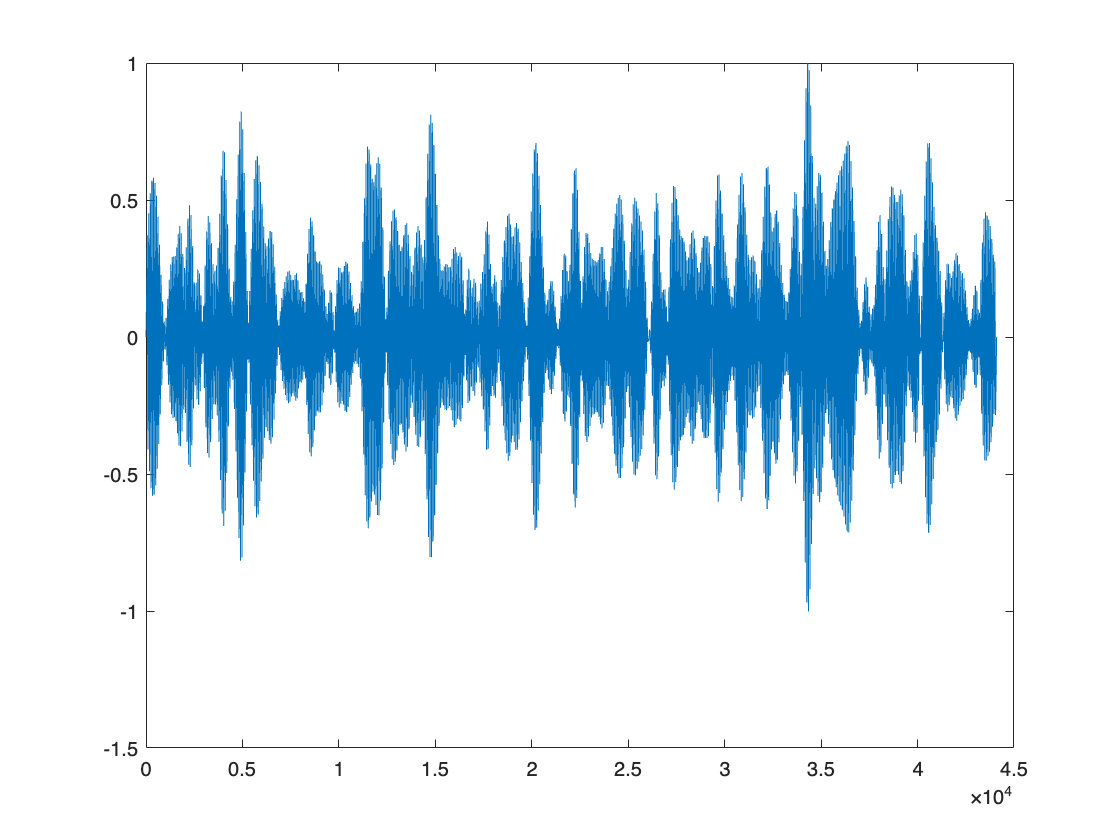

recs = [prepend recs append];
plot((1:L),recs);

recs(1)

ans = 0

recs(end)

ans = 0

min(recs)

ans = -1.0015

max(recs)

ans = 1

audiowrite("recr.wav",recs,Fs)